# Channel models

This code plots the magnitude and the Probability Density Fucntions (PDF) of different propagation channel models, namely, the Rayleigh channel and the Rice channel. This code requieres the **Statistics and Machine Learning Toolbox.**

clc;                                        % Clear the command window screen
clear all;                                  % Erase all existing variables
close all;                                  % Close all figure windows

## Guidelines: what to do?

This code uses the following function:

- generate_channel

The goal is to develop the missing code in the function *generate_channel*.

Once this is done, it is necessary to compare the obtained distributions with the expected ones. In particular, for the Rayleigh channel model, the magnitude of the channel has a Rayleigh distribution and the phase is uniformy distributed over $2\pi$. The Rice channel model magnitude has a Rice distribution. So, observe the statistical distribution obtained by simulation and check whether it fits the expected PDF. The expected Rayleigh or Rice distributions are available with the Matab function *pdf*.

Once this is working, observe the channel magnitude and the PDF of the Rice channel when varying the Rice factor *K* (between -20dB and 20dB). Compare with the Rayleigh channel.

## Input parameters

nb_realization = 1e5 ;
K_dB = 0 ;                                                          % Rice factor K in dB scale

## Rayleigh model

The channel is considered constant over the entire frame duration but changes for each frame. Consequently, the channel is here generated with a length equal to the number of frames that is to be transmitted

H_rayleigh = generate_channel( nb_realization , 'Rayleigh' ) ;      % Generate the channel

#### Channel magnitude plot

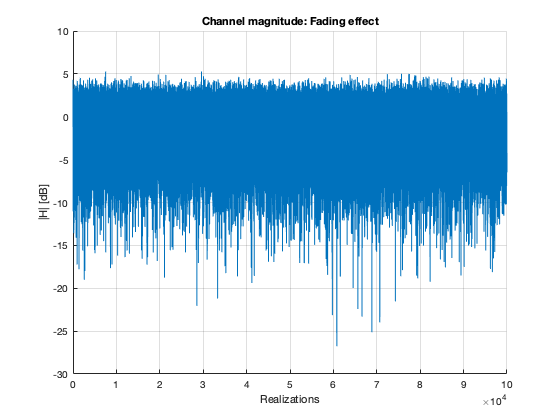

figure
title( 'Channel magnitude: Fading effect' )
hold on
grid on
plot( 10 * log10( abs( H_rayleigh ) ) )
xlabel('Realizations')
ylabel('|H| [dB]')

#### Channel statistical distributions

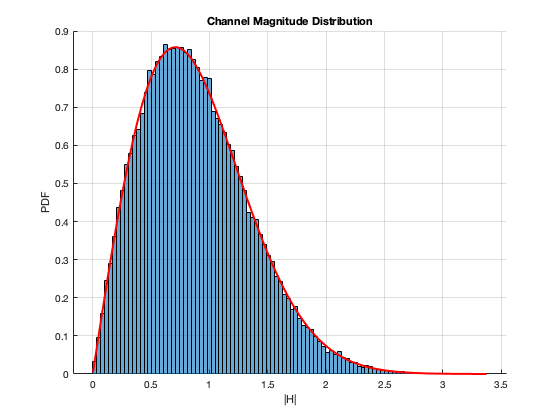

figure
title('Channel Magnitude Distribution')
hold on
histogram( abs( H_rayleigh ) , 100 , 'Normalization' , 'pdf') ;
x_min = min( abs( H_rayleigh ) ) ;
x_max = max( abs( H_rayleigh ) ) ;
x = linspace( x_min , x_max , 100 ) ;
sigma = 1 / sqrt( 2 ) ;
plot( x , pdf( 'Rayleigh' , x , sigma ) , 'r', "LineWidth", 2 ) ;
hold on
grid on
xlabel('|H|')
ylabel('PDF')

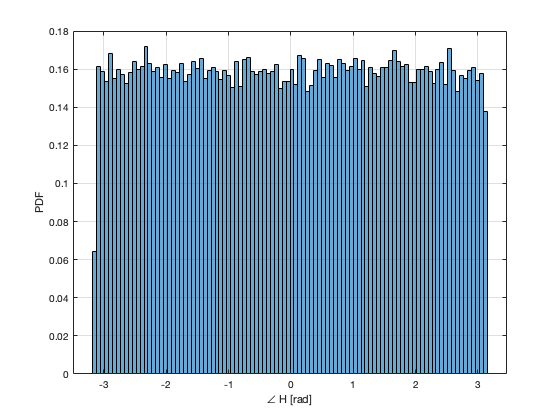


figure
title('Channel Phase Distribution')
histogram( angle( H_rayleigh ) , 100 , 'Normalization' , 'pdf') ;
hold on
grid on
xlabel('\angle H [rad]')
ylabel('PDF')


Expectation_H_Rayleigh_power = mean( abs( H_rayleigh ).^2 )     % Calculation of the expectation of the channel power

Expectation_H_Rayleigh_power = 0.9945

## Rice model

K = 10^( K_dB / 10 ) ;                                          % Conversion of the Rice factor from dB to linear scale
H_rice = generate_channel( nb_realization , 'Rice' , K ) ;      % Generate the channel

#### Channel magnitude plot

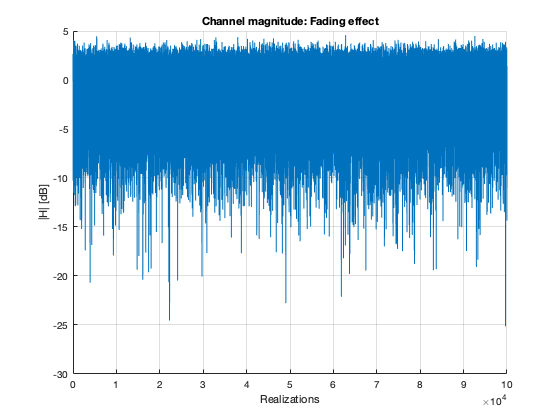

figure
title( 'Channel magnitude: Fading effect' )
hold on
grid on
plot( 10 * log10( abs( H_rice ) ) )
xlabel('Realizations')
ylabel('|H| [dB]')

#### Channel statistical distributions

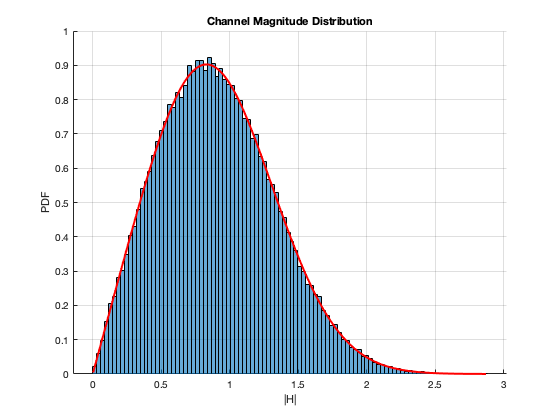

figure
title('Channel Magnitude Distribution')
hold on
histogram( abs( H_rice ) , 100 , 'Normalization' , 'pdf') ;
x_min = min( abs( H_rice ) ) ;
x_max = max( abs( H_rice ) ) ;
x = linspace( x_min , x_max , 100 ) ;
sigma = sqrt( 1 / ( 1 + K ) ) / sqrt( 2 )  ;
s = sqrt( 2 * K) * sigma ;
plot( x , pdf( 'Rician' , x , s , sigma ) , 'r', "LineWidth", 2 ) ;
hold on
grid on
xlabel('|H|')
ylabel('PDF')

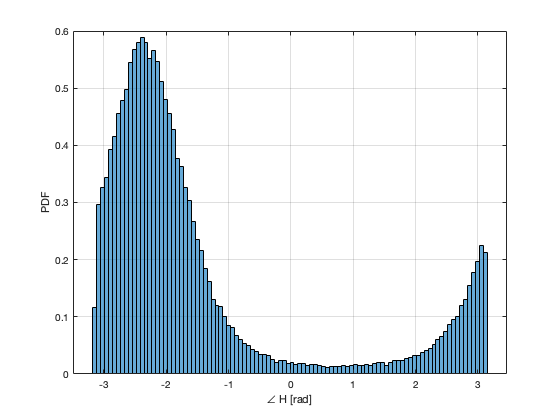


figure
title('Channel Phase Distribution')
histogram( angle( H_rice ) , 100 , 'Normalization' , 'pdf') ;
hold on
grid on
xlabel('\angle H [rad]')
ylabel('PDF')


Expectation_H_Rice = mean( abs( H_rice ).^2 )                   % Calculation of the expectation of the channel power

Expectation_H_Rice = 1.0000